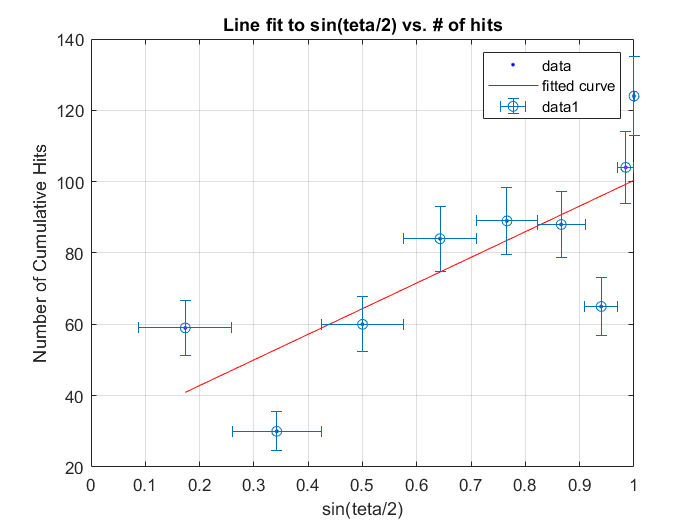


%% Fit: 'line fit'.
[xData, yData] = prepareCurveData( sintetahalf, n2 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );

%creating error bars in degrees
hold on
xerrorpos=[0.086 0.082 0.076 0.067 0.056 0.044 0.030 0.015 0];
xerrneg=xerrorpos;
errypos=sqrt(n2);
erryneg=errypos;
errorbar(sintetahalf,n2,erryneg,errypos,xerrneg,xerrorpos,'o');

% Label axes

xlabel sin(teta/2)
ylabel 'Number of Cumulative Hits'
grid on

title('Line fit to sin(teta/2) vs. # of hits')



%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       71.91  (18.34, 125.5)
  %     p2 =       28.45  (-11.48, 68.38)

%Goodness of fit:
 % SSE: 2545
  %R-square: 0.59
  %Adjusted R-square: 0.5315
  %RMSE: 19.07